# State feedback control, state estimation, continuous systems: Case studies

The script assumes familiarity with all of the earlier files in the state space section of the toolbox. The purpose here is to undertake case studies showing how the different analysis and design tool can be used to formulate a control feedback design. The design method used here is pole placement. This live script needs the control toolbox. 

These notes give a concise engineering and analytical background alongside some simple MATLAB code snippets that can be used for equivalent analysis.

In addition to the files referred above this file summarises the principles and visualises them with block diagrams. As a case study it shows state feedback control of a third order proportional system first with measurable, then with estimated state variables. The state feedback control of the same system extended with an integrator is also shown. It is demonstrated that it is easy to stabilise and control an unstable system by state feedback. 

To avoid excessive displays of matrices, in many cases the results are not automatically displayed. Remove the semi-colons and use run section to view details you may be interested in.

### Useful resources and similar files and the toolbox

**Control Engineering **and** Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019** 

[https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

Within the control101 toolbox files, you can specifically look look also files **statespace_models_control101, state_feedback_control101, observer_design_control101.**

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars and László Keviczky, Budapest University of Technology and Economics with edits by J.A. Rossiter, University of Sheffield       

                             

Referred files were written by                                                               

## Table of contents

- State space representation of Single Input Single Output systems

- The concept of state feedback control

- State feedback with pole placement

- Introducing an integrator into the control loop

- State estimation

- State feedback with state estimation

## 1. State space representation of Single Input Single Output Systems

In a system besides the input and output variables internal variables can also be considered whose values do not change abruptly when a step-like change is applied in the input signal. These inner signals represent information determined by the past history of the system. The set of these signals are called state variables. Such signals in a physical system are e.g. speed, temperature, pressure, etc. A system can be described by several sets of state variables, as any linear combination of the original state variables gives a new state space representation while providing the same input-output relationship. While with input-output representation a SISO system is described by an n-order differential equation, its state space description gives n number of first order differential equations.

The set $\lbrace \mathit{\mathbf{A}},\mathit{\mathbf{b}},{\mathit{\mathbf{c}}}^T ,d\rbrace$ of parameter matrices exhibits a SISO system representation with input *u, *output *y *and state vector ***x ***in the model


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{bu}\\
y={\mathit{\mathbf{c}}}^T \mathit{\mathbf{x}}+\textrm{du}
\end{array}$$


***A*** is an *n* X *n* quadratic matrix, ***b*** is an *n* X 1 column vector, ${\mathit{\mathbf{c}}}^T$is a 1 X *n* row vector and *d* is a constant. The system model characterised by the four parameters  is called state model. In most  the practical cases *d*=0.

The equations above (the state equation and the output equation) determine the transfer function between the  input signal and the  output signal, which is calculated as 


$$G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}={\mathit{\mathbf{c}}}^T {\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} \mathit{\mathbf{b}}+d$$


The poles of the model are the roots of the characteristic equation


$$\det \left(\textrm{sI}-\mathit{\mathbf{A}}\right)=0$$
      

## 2. The concept of state feedback control

 By state feedback the control signal is obtained from the state variables feeding them back to the input through the constant elements of a vector or state feedback gain ${\mathit{\mathbf{k}}}^T$. The control signal is obtained as:


$$u=k_r r-{\mathit{\mathbf{k}}}^T \mathit{\mathbf{x}}$$


where $k_r$ is a compensation factor ensuring the required steady state value (in the nominal case - see ***tracking_with_statespace_control101 ***and*** state_space_and_simulinkfile1_control101***).

The state feedback control can be represented with a block diagram as shown in the figure 2.1 below; the inner block indicated with the hashed lines is the model and the outer blocks denoted the controller aspects. State feedback modifies both the static and the dynamic response of the system between the reference signal *r* and the output signal *y*.  

                    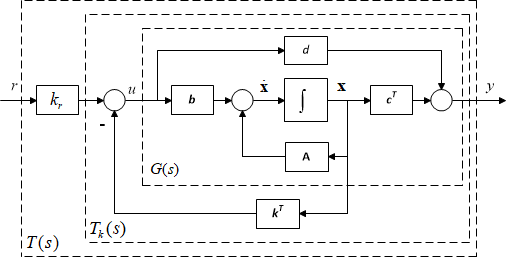

**Figure 2.1:** Block diagram representation of closed-loop control with state space systems

The equations of the state feedback system are:


$$\dot{\mathit{\mathbf{x}}} =\left(\mathit{\mathbf{A}}-\mathit{\mathbf{b}}{\mathit{\mathbf{k}}}^T \right)+k_r \textrm{br}$$



$$y=\left({\mathit{\mathbf{c}}}^T -d{\mathit{\mathbf{k}}}^T \right)\mathit{\mathbf{x}}+dk_r r$$


The characteristic equation is modified to:


$$\det \left(\textrm{sI}-\mathit{\mathbf{A}}+\mathit{\mathbf{b}}{\mathit{\mathbf{k}}}^T \right)=0$$


## 3. State feedback with pole placement

The design of the state feedback gain ${\mathit{\mathbf{k}}}^T$ is executed in three steps.

a. Choose the desired location of the poles of the closed loop system.

b. Determine the state feedback vector ensuring the given poles using the Ackermann formula (or other methods, e.g. ***state_feedback_control101***). The matlab command `acker` can be applied.   (For theoretical background and exercises look at  [state space feedback 4 - ackermanns approachpdf.pdf ](https://drive.google.com/file/d/1Vo2Q2bjeqK3yDimv3zWOflkjr5edvBYk/view))

c. Determine the compensation factor to fulfill the static requirements.

#### 3.1 State feedback controller design for a third order proportional process

As an example consider a third order process. The transfer function of the process is:


$$G\left(s\right)=\frac{6\ldotp 2}{\left(s+1\right)\left(s+2\right)\left(s+3\right)}$$


|We desired to accelerate the system, so move t he poles further into the LHP. Hence, choose the desired poles of the closed loop as:

*pk=[-6;-3+i*4;-3-i*4]*

(The conjugate complex poles can be considered as the poles of a second order oscillating system. The associated damping factor $\xi$ is calculated from the angle $\varphi$ of the vector of the poles, $\xi =\cos \varphi =\frac{3}{\sqrt{9+16}}$=0.6.)

The associated design steps and a plot of the closed-loop the step response are given in the code below. Note that the use of $k_r$ ensures a closed-loop gain of unity, in the nominal case whereas this may not be the case for the open-loop system.

disp('SECTION 3.1: A STATE FEEDBACK CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS')

DESIGN A STATE FEEDBACK CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS


disp('The process')

The process


num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den)

G =
 
           6.2
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


disp('The controllability canonical form of the state equation')

The controllability canonical form of the state equation


[A,b,c,d]=tf2ss(num,den)

A =     -6   -11    -6
     1     0     0
     0     1     0


b =      1
     0
     0


c =          0         0    6.2000


d = 0

disp('The desired poles of the closed loop system')

The desired poles of the closed loop system


pk=[-6;-3+i*4;-3-i*4]

pk =   -6.0000 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i


disp('Determine the state feedback vector using the Ackermann formula')

Determine the state feedback vector using the Ackermann formula


k=acker(A,b,pk)

k =      6    50   144


disp('State equation of the closed loop')

State equation of the closed loop


Tk=ss(A-b*k,b,c,d)

Tk =
 
  A = 
         x1    x2    x3
   x1   -12   -61  -150
   x2     1     0     0
   x3     0     1     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1    0    0  6.2
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


disp('Feedforward design to ensure no steady-state offset')

Steady state compensation factor


kr=1/dcgain(Tk)

kr = 24.1935

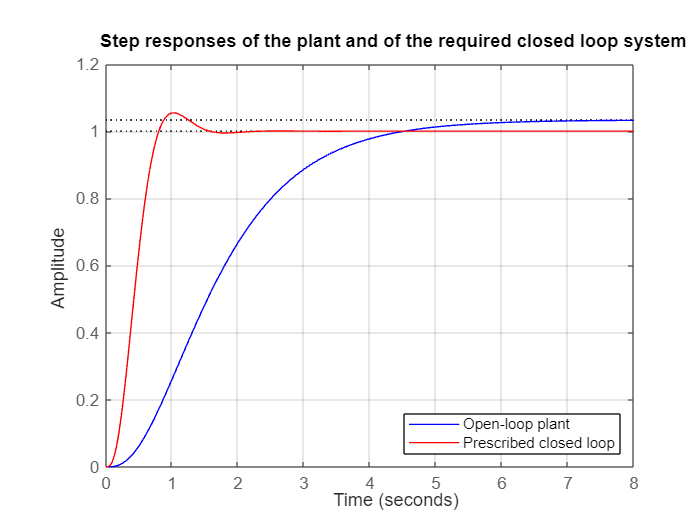


% Open and Closed-loop responses
runtime=8;
step(G,'b',Tk*kr,'r',runtime),grid
title('Step responses of the plant and of the closed loop system ')
legend('Open-loop','Closed loop','Location','southeast')

#### 3.2 State feedback controller design for an unstable process

With state feedback unstable processes can be stabilised easily, of course assuming controllabillity (***controllability_and_observability_control101***). Just stable poles should be prescribed for the closed loop system.

As an example consider the process given by the following unstable transfer function:


$$G\left(s\right)=\frac{-6}{\left(s-1\right)\left(s+2\right)\left(s+3\right)}$$


The process is unstable as its transfer function contains one pole on the right side of the complex plane. Choose the poles of the closed loop to give some speed up of the slower open-loop poles, and of course to be all stable.

*pk=[-6;-3+i*4;-3-i*4]*

Determine the state feedback vector and plot the step response of the closed loop.

disp('SECTION 3.2: A STATE FEEDBACK CONTROLLER FOR AN UNSTABLE PROCESS')

DESIGN A STATE FEEDBACK CONTROLLER FOR AN UNSTABLE PROCESS


disp('The process')

The process


num=-6;
den=poly([1,-2,-3]);
G=tf(num,den)

G =
 
          -6
  -------------------
  s^3 + 4 s^2 + s - 6
 
Continuous-time transfer function.
Model Properties


disp('The controllability canonical form of the state equation')

The controllability canonical form of the state equation


[A,b,c,d]=tf2ss(num,den)

A =     -4    -1     6
     1     0     0
     0     1     0


b =      1
     0
     0


c =      0     0    -6


d = 0

disp('The prescribed poles of the closed loop system')

The prescribed poles of the closed loop system


pk=[-6;-3+i*4;-3-i*4]

pk =   -6.0000 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i


disp('Determine the state feedback vector')

Determine the state feedback vector using the Ackermann formula


k=acker(A,b,pk)

k =      8    60   156


disp('State equation of the closed loop')

State equation of the closed loop


Tk2=ss(A-b*k,b,c,d)

Tk2 =
 
  A = 
         x1    x2    x3
   x1   -12   -61  -150
   x2     1     0     0
   x3     0     1     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   0  -6
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


disp('Steady state compensation factor')

Steady state compensation factor


kr=1/dcgain(Tk2)

kr = -25.0000

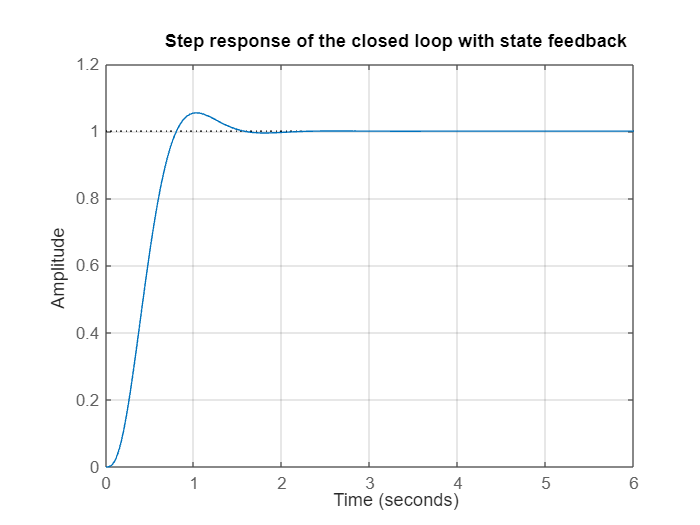


% Closed-loop responses
runtime=6;
step(Tk2*kr,runtime),grid
title('Step response of the closed loop with state feedback')

## 4. Introducing an integrator into the control loop

With the compensation factor the accuracy of the step response can be ensured, but it depends on the accurate knowledge of the parameters of the system. Disturbance rejection also is not ensured. By enhancing the state equation with an extra state variable which is the integral of the output signal the accurate step reference tracking and step disturbance rejection can be realised. See ***observer_design_control101, state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***.

The block diagram of the extended system is shown in the figure 4.1 below.

                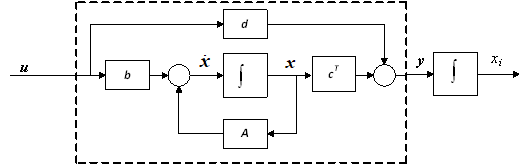

**Figure 4.1:** Block diagram representation of integral action with state space systems

The state equation of the extended system is


$$\left\lbrack \begin{array}{c}
\dot{\mathit{\mathbf{x}}} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathit{\mathbf{A}} & 0\\
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
x_i 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\mathit{\mathbf{b}}\\
0
\end{array}\right\rbrack u={\mathit{\mathbf{A}}}_e {\mathit{\mathbf{x}}}_e +{\mathit{\mathbf{b}}}_e u$$



$$y=\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
x_i 
\end{array}\right\rbrack +\textrm{du}={\mathit{\mathbf{c}}}_e^T {\mathit{\mathbf{x}}}_e +\textrm{du}$$


So the number of the state variables is increased by 1 (SISO case). For state feedback design the number of the prescribed poles should also be increased by 1.  The state feedback vector is then calculated for the extended system  and thus the prescribed poles are the roots of the characteristic equation:


$$\det \left(\textrm{sI}-{\mathit{\mathbf{A}}}_e +{\mathit{\mathbf{b}}}_e {\mathit{\mathbf{k}}}_e^T \right)=0$$


The figure 4.2 below shows the extended state feedback system. The integrator is located after the error signal.

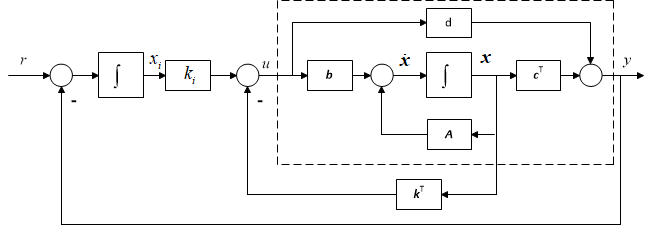

**Figure 4.2:** Block diagram representation of closed-loop control with integral action with state space systems

The state equation of the closed loop system with state feedback supposing d=0 is the following:


$$\dot{{\mathit{\mathbf{x}}}_z } =\left\lbrack \begin{array}{c}
\dot{\mathit{\mathbf{x}}} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathit{\mathbf{A}}-\mathit{\mathbf{b}}{\mathit{\mathbf{k}}}^T  & \mathit{\mathbf{b}}k_i \\
-{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
x_i 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack r={\mathit{\mathbf{A}}}_z {\mathit{\mathbf{x}}}_z +{\mathit{\mathbf{b}}}_z r$$



$$y=\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
x_i 
\end{array}\right\rbrack +0\ldotp r={\mathit{\mathbf{c}}}_z^T {\mathit{\mathbf{x}}}_z +0\ldotp r$$


#### 4.1 State feedback of a third order process extended with an integrator

This section gives the code which extends the design for the third order process given in example 3.1 with an integrator, observer and  a state feedback controller. As expected, the closed-loop has a unity gain and no offset.

disp('SECTION 4.1:  A STATE FEEDBACK CONTROLLER FOR A PROCESS EXTENDED WITH AN INTEGRATOR')

SECTION 4.1:  A STATE FEEDBACK CONTROLLER FOR A PROCESS EXTENDED WITH AN INTEGRATOR


disp('The process')

The process


num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den)

G =
 
            6
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


disp('The controllability canonical form of the state equation')

The controllability canonical form of the state equation


[A,b,c,d]=tf2ss(num,den)

A =     -6   -11    -6
     1     0     0
     0     1     0


b =      1
     0
     0


c =      0     0     6


d = 0

disp('Parameter matrices of the extended system')

Parameter matrices of the extended system


nulvec=[0;0;0];
Ae=[A nulvec;c 0]

Ae =     -6   -11    -6     0
     1     0     0     0
     0     1     0     0
     0     0     6     0


be=[b;0]

be =      1
     0
     0
     0


disp('The prescribed poles of the closed loop system')

The prescribed poles of the closed loop system


pe=[-9 -6 -3+i*4 -3-i*4]

pe =   -9.0000 + 0.0000i  -6.0000 + 0.0000i  -3.0000 + 4.0000i  -3.0000 - 4.0000i


disp('Determine the state feedback vector')

Determine the state feedback vector


ke=acker(Ae,be,pe)

ke =     15   158   693   225


ki=ke(4);
k=ke(1:3);

The first three elements of the extended state feedback vector realise the state feedback from the original state variables, while the fourth element belongs to the artificially introduced integrator.

disp('The state matrices of the closed loop system')

The state matrices of the closed loop system


Az=[A-b*k b*ki;-c 0]

Az =    -21  -169  -699   225
     1     0     0     0
     0     1     0     0
     0     0    -6     0


bz=[nulvec;1]

bz =      0
     0
     0
     1


cz=[c 0]

cz =      0     0     6     0


dz=0

dz = 0


% Closed-loop responses
t=0:0.1:6;

Step response of the closed loop


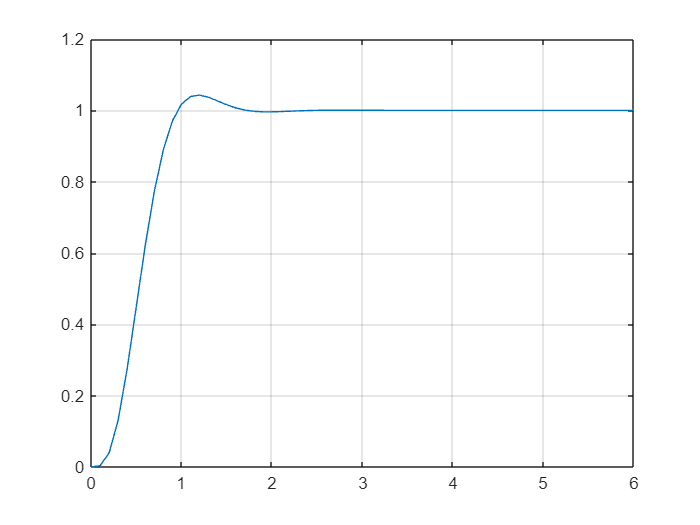

y=step(Az,bz,cz,dz,1,t);
plot(t,y),grid

title('Step response of the closed loop')

## **5. State estimation**

In practical applications generally only the output signal can be measured and the state variables or some of the state variables are not available. In this case the state variables have to be estimated. The block scheme of the state estimator is shown in the figure 5.1 below. The estimator contains the model of the system. It is assumed that d=0. For slower explanations see: ***observer_design_control101, state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***.

                 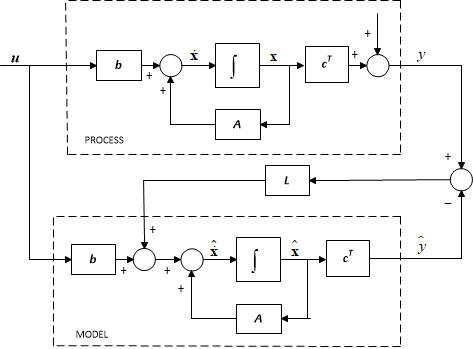

**Figure 5.1:** Block diagram representation of closed-loop control with integral action and an observer

If the system is known, the parameter matrices of the model are the same as the parameter matrices of the system. The deviation between the output signal of the system and that of the model is caused mainly by the difference of the initial conditions of the system and those supposed in the model. This error signal is fed back to the summing point at the derivatives of the estimated state variables and modifies their values. The estimated state variables should move quickly to approximate the motion of the real state variables. An important requirement is that the dynamics of the estimation circuit should be much faster than the dynamics of the process itself. The state estimation circuit forms a closed loop where the input signal is y (i.e.the output signal of the process). 

The free motion of the system states is to be estimated, i.e. the motion of the state variables starting from their initial values, supposing zero input signal. The disturbance signal is supposed to be zero.

The estimated state variables can be calculated as:


$$\dot{\hat{\mathit{\mathbf{x}}} } =\mathit{\mathbf{A}}\hat{\mathit{\mathbf{x}}} +\textrm{bu}+\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T \left(\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} \right)=\left(\mathit{\mathbf{A}}-\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T \right)\hat{\mathit{\mathbf{x}}} +\textrm{Ly}$$


Introducing the error signal $\varepsilon =\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}}$


$$\dot{\varepsilon} =\mathit{\mathbf{A}}\varepsilon -\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T \varepsilon =\mathit{\mathbf{A}}\varepsilon -\mathit{\mathbf{L}}\left(y-\hat{y} \right)$$


The estimation circuit can be redrawn according to the following figure 5.2.

         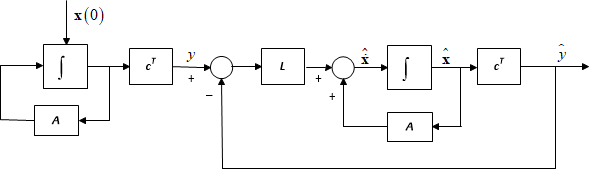

**Figure 5.2:** Block diagram representation of an observer

The poles of the estimation circuit can be prescribed. If the prescribed roots of the characteristic equation are denoted by Pe, the vector *L* can be calculated by the matlab command:

***L=acker(A',c',Pe)'***

The code below demonstrates the estimation process, for now in open-loop only.  It is seen that although there are inevitably errors during transients, in the nominal case the state estimates converge to the true state values.

disp('SECTION 5: ESTIMATE THE STATE VARIABLES OF A THIRD ORDER PROCESS')

SECTION 5: ESTIMATE THE STATE VARIABLES OF A THIRD ORDER PROCESS


num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den);
disp('The controllability canonical form of the state equation')

The controllability canonical form of the state equation


[A,b,c,d]=tf2ss(num,den)

A =     -6   -11    -6
     1     0     0
     0     1     0


b =      1
     0
     0


c =      0     0     6


d = 0

sys1=ss(A,b,c,d);

% The response with non-zero initial conditions')
x0=[1;1;1];
t=0:0.05:6;
[y,t,x]=initial(sys1,x0,t);

% Adding an observer
disp('Prescribed poles of the estimation circuit')

Prescribed poles of the estimation circuit


Pe=[-7 -7 -7]

Pe =     -7    -7    -7


disp('State estimation vector')

State estimation vector


L=acker(A',c',Pe)

L =   -17.3333    7.6667    2.5000


Aest=A-L'*c;
sysest=ss(Aest,L',c,d)

sysest =
 
  A = 
        x1   x2   x3
   x1   -6  -11   98
   x2    1    0  -46
   x3    0    1  -15
 
  B = 
           u1
   x1  -17.33
   x2   7.667
   x3     2.5
 
  C = 
       x1  x2  x3
   y1   0   0   6
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


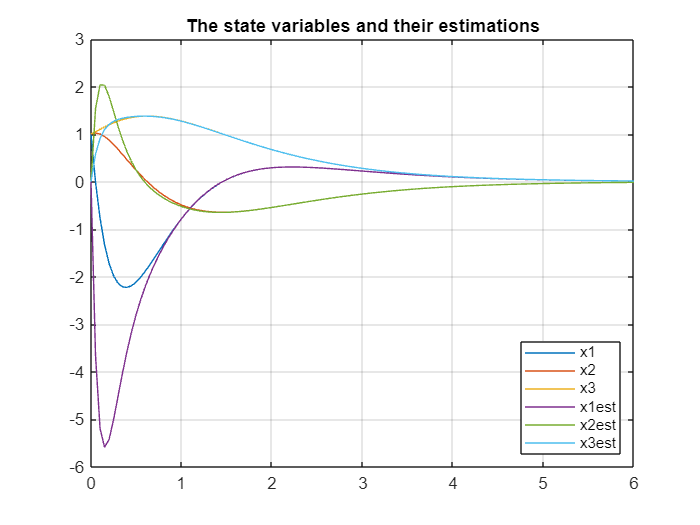

x0est=[0;0;0];

% Closed-loop simulations and plotting
[yest,t,xest]=lsim(sysest,y,t,x0est);
plot(t,x,t,xest),grid
title('The state variables and their estimations')
legend('x1','x2','x3','x1est','x2est','x3est','Location','southeast')

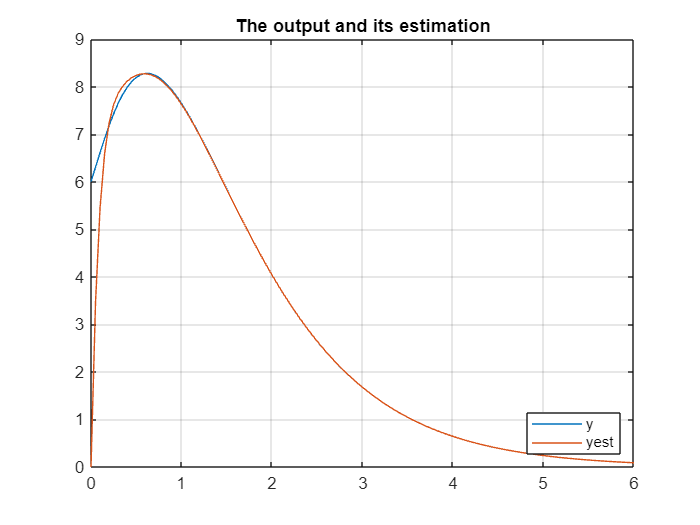

plot(t,y,t,yest),grid
title('The output and its estimation')
legend('y','yest','Location','southeast')

## **6. State feedback with state estimation**

If the state variables are not available, then state feedback control can be realised by feeding back the estimated state variables with the state feedback vector calculated for the original state variables (separation principle). The dynamics of the state feedback circuit should be faster than the process dynamics, and the dynamics of the state estimation circuit should be faster than the dynamics of the state feedback circuit.

The block diagram of the state feedback circuit using state estimation (observer) is given in the figure 6.1 below.

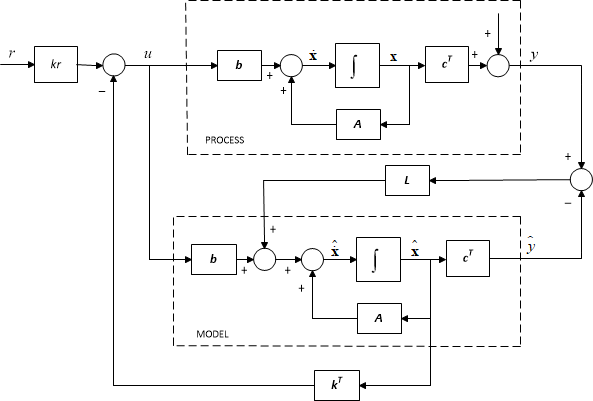

**Figure 6.1:** Block diagram representation of closed-loop control with integral action and an observer

The state equations of this system with state estimation and state feedback are:


$$\left\lbrack \begin{array}{c}
\dot{\mathit{\mathbf{x}}} \\
\dot{\hat{\mathit{\mathbf{x}}} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathit{\mathbf{A}} & -\mathit{\mathbf{b}}{\mathit{\mathbf{k}}}^T \\
\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T  & \mathit{\mathbf{A}}-\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T -\mathit{\mathbf{b}}{\mathit{\mathbf{k}}}^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
\hat{\mathit{\mathbf{x}}} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\mathit{\mathbf{b}}k_r \\
\mathit{\mathbf{b}}k_r 
\end{array}\right\rbrack r$$



$$y=\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
\hat{\mathit{\mathbf{x}}} 
\end{array}\right\rbrack +0\ldotp r$$


The code below shows how one can easily perform all the design and evaluation steps in relatively simply steps and compare the behaviour of the control system when state feedback is taken from the true and estimated state variables.

disp('SECTION 6: STATE FEEDBACK CONTROLLER USING ESTIMATED STATES')

SECTION 6: STATE FEEDBACK CONTROLLER USING ESTIMATED STATES


disp('')
num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den);
disp('The controllability canonical form of the state equation')

The controllability canonical form of the state equation


[A,b,c,d]=tf2ss(num,den)

A =     -6   -11    -6
     1     0     0
     0     1     0


b =      1
     0
     0


c =      0     0     6


d = 0

sys1=ss(A,b,c,d);

% State feedback design and feedforward
disp('Prescribed poles of the closed loop system')

Prescribed poles of the closed loop system


pk=[-6;-3+i*4;-3-i*4]

pk =   -6.0000 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i


disp('Determine the state feedback vector using the Ackermann formula')

Determine the state feedback vector using the Ackermann formula


k=acker(A,b,pk)

k =      6    50   144


sys2=ss(A-b*k,b,c,d);
disp('Static gain')

Static gain


kr=1/dcgain(sys2)

kr = 25.0000

% State equation of the state feedback system
sys3=ss(A-b*k,b*kr,c,d);

% Responses without an observer
disp('Initial conditions')

Initial conditions


x0=[0.2;0.2;0.2]

x0 =     0.2000
    0.2000
    0.2000


t=0:0.05:3;
[y1,t,x]=initial(sys3,x0,t); % response with non-zero initial conditions
y2=step(sys3,t);             % units step response

% Observer computations and responses with an observer
disp('Prescribed poles for state estimation')

Prescribed poles for state estimation


pe=[-7 -7 -7]

pe =     -7    -7    -7


disp('The state estimation vector')

The state estimation vector


L=acker(A',c',pe)

L =   -17.3333    7.6667    2.5000


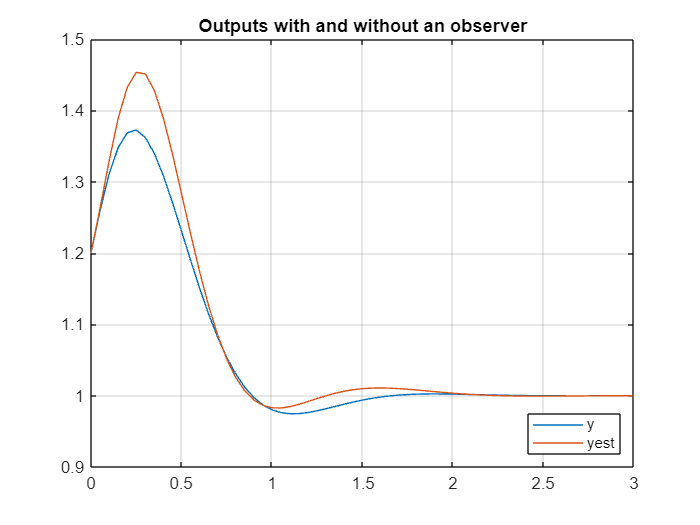

Af=[A -b*k;L'*c A-L'*c-b*k];
bf=[b*kr;b*kr];
cf=[c zeros(1,3)];
df=0;
% State equation of the system enhanced with state estimation')
sys4=ss(Af,bf,cf,df);
x0est=[0;0;0];
x0f=[x0;x0est];
[y3,t,x3]=initial(sys4,x0f,t);
y4=step(sys4,t);


% Comparison of the closed-loop behaviours (outputs and states)
plot(t,y1+y2,t,y3+y4),grid
legend('y','yest','Location','southeast')
title('Outputs with and without an observer')

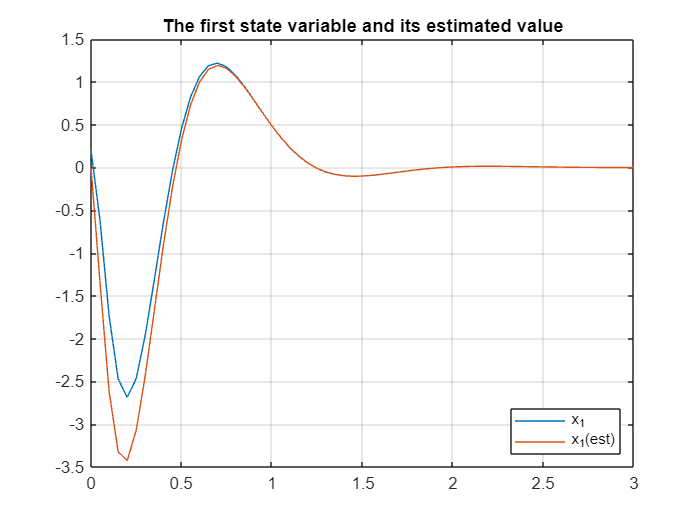


plot(t,x3(:,1),t,x3(:,4)),grid
legend('x_1','x_1(est)','Location','southeast')
title('The first state variable and its estimated value')

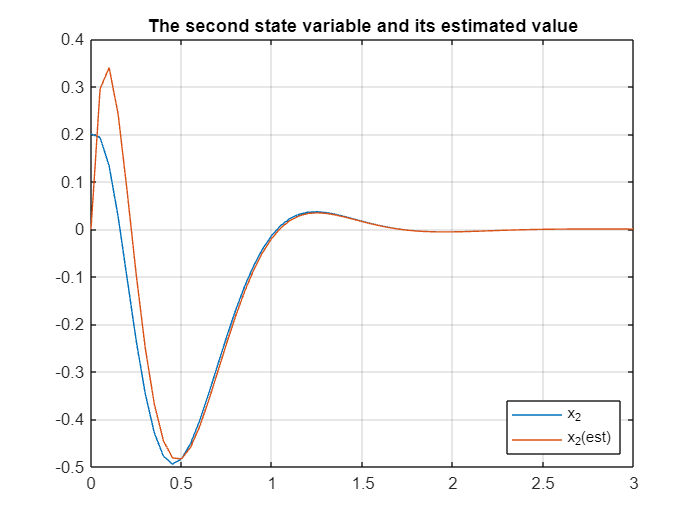

plot(t,x3(:,2),t,x3(:,5)),grid
legend('x_2','x_2(est)','Location','southeast')
title('The second state variable and its estimated value')

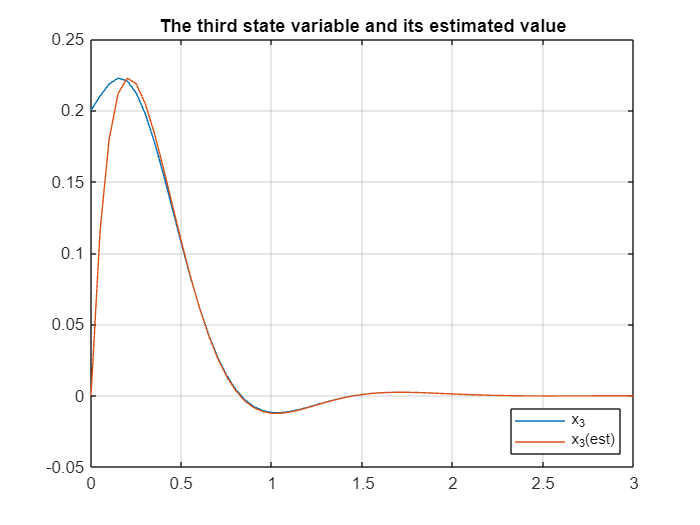

plot(t,x3(:,3),t,x3(:,6)),grid
legend('x_3','x_3(est)','Location','southeast')
title('The third state variable and its estimated value')

It is seen that the estimation of the state variables is acceptable and the control is good for both cases, when the state feedback is taken from the original states or from the estimated state variables.